s = polygon([0,1,1+i,i]) %define the polygon (a square)

s = polygon object:

       Vertex         Angle/pi
  ----------------------------
  0.0000 + 0.0000i     0.5000
  1.0000 + 0.0000i     0.5000
  1.0000 + 1.0000i     0.5000
  0.0000 + 1.0000i     0.5000




f = hplmap(s) %generate the map from UHP to square

 
  hplmap object:
 
      vertex               alpha         prevertex       
 --------------------------------------------------------
  0.00000 + 0.00000i      0.50000     -1.000000000000e+00
  1.00000 + 0.00000i      0.50000      0.000000000000e+00
  1.00000 + 1.00000i      0.50000      1.000000000000e+00
  0.00000 + 1.00000i      0.50000                     Inf
 
  c = -0.38137988 + 4.6705565e-17i
 
  Apparent accuracy is 5.59e-12
 



%discretise the unit square
[X,Y] = meshgrid(0:0.01:1)

X =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0

Y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0

Z = X+i*Y

Z =    0.0000 + 0.0000i   0.0100 + 0.0000i   0.0200 + 0.0000i   0.0300 + 0.0000i   0.0400 + 0.0000i   0.0500 + 0.0000i   0.0600 + 0.0000i   0.0700 + 0.0000i   0.0800 + 0.0000i   0.0900 + 0.0000i   0.1000 + 0.0000i   0.1100 + 0.0000i   0.1200 + 0.0000i   0.1300 + 0.0000i   0.1400 + 0.0000i   0.1500 + 0.0000i   0.1600 + 0.0000i   0.1700 + 0.0000i   0.1800 + 0.0000i   0.1900 + 0.0000i   0.2000 + 0.0000i   0.2100 + 0.0000i   0.2200 + 0.0000i   0.2300 + 0.0000i   0.2400 + 0.0000i   0.2500 + 0.0000i   0.2600 + 0.0000i   0.2700 + 0.0000i   0.2800 + 0.0000i   0.2900 + 0.0000i   0.3000 + 0.0000i   0.3100 + 0.0000i   0.3200 + 0.0000i   0.3300 + 0.0000i   0.3400 + 0.0000i   0.3500 + 0.0000i   0.3600 + 0.0000i   0.3700 + 0.0000i   0.3800 + 0.0000i   0.3900 + 0.0000i   0.4000 + 0.0000i   0.4100 + 0.0000i   0.4200 + 0.0000i   0.4300 + 0.0000i   0.4400 + 0.0000i   0.4500 + 0.0000i   0.4600 + 0.0000i   0.4700 + 0.0000i   0.4800 + 0.0000i   0.4900 + 0.0000i
   0.0000 + 0.0100i   0.0100 + 0.0100i   0.02


%find the potential, V: V = Re(h) = Re(g(finv(z)))

finv = evalinv(f,Z) %find parameter xi in terms of z

finv = 	1.0e+03 *

  -0.0010 + 0.0000i  -0.0010 + 0.0000i  -0.0010 + 0.0000i  -0.0010 + 0.0000i  -0.0010 + 0.0000i  -0.0010 + 0.0000i  -0.0010 + 0.0000i  -0.0010 + 0.0000i  -0.0010 + 0.0000i  -0.0010 + 0.0000i  -0.0010 + 0.0000i  -0.0010 + 0.0000i  -0.0010 + 0.0000i  -0.0009 + 0.0000i  -0.0009 + 0.0000i  -0.0009 + 0.0000i  -0.0009 + 0.0000i  -0.0009 + 0.0000i  -0.0009 + 0.0000i  -0.0009 + 0.0000i  -0.0009 + 0.0000i  -0.0009 + 0.0000i  -0.0008 + 0.0000i  -0.0008 + 0.0000i  -0.0008 + 0.0000i  -0.0008 + 0.0000i  -0.0008 + 0.0000i  -0.0008 + 0.0000i  -0.0008 + 0.0000i  -0.0007 + 0.0000i  -0.0007 + 0.0000i  -0.0007 + 0.0000i  -0.0007 + 0.0000i  -0.0007 + 0.0000i  -0.0007 + 0.0000i  -0.0007 + 0.0000i  -0.0006 + 0.0000i  -0.0006 + 0.0000i  -0.0006 + 0.0000i  -0.0006 + 0.0000i  -0.0006 + 0.0000i  -0.0006 + 0.0000i  -0.0005 + 0.0000i  -0.0005 + 0.0000i  -0.0005 + 0.0000i  -0.0005 + 0.0000i  -0.0005 + 0.0000i  -0.0005 + 0.0000i  -0.0004 + 0.0000i  -0.0004 + 0.0000i
  -0.0010 + 0.0000i  -0.0010 +

h = k(finv) %find harmonic function in terms of z

w =    0.0000 + 0.0000i   0.0083 + 0.0000i   0.0167 + 0.0000i   0.0250 + 0.0000i   0.0334 + 0.0000i   0.0417 + 0.0000i   0.0500 + 0.0000i   0.0583 + 0.0000i   0.0665 + 0.0000i   0.0748 + 0.0000i   0.0830 + 0.0000i   0.0912 + 0.0000i   0.0993 + 0.0000i   0.1075 + 0.0000i   0.1155 + 0.0000i   0.1236 + 0.0000i   0.1316 + 0.0000i   0.1396 + 0.0000i   0.1475 + 0.0000i   0.1554 + 0.0000i   0.1632 + 0.0000i   0.1709 + 0.0000i   0.1786 + 0.0000i   0.1863 + 0.0000i   0.1939 + 0.0000i   0.2014 + 0.0000i   0.2089 + 0.0000i   0.2163 + 0.0000i   0.2236 + 0.0000i   0.2309 + 0.0000i   0.2380 + 0.0000i   0.2451 + 0.0000i   0.2522 + 0.0000i   0.2591 + 0.0000i   0.2660 + 0.0000i   0.2728 + 0.0000i   0.2795 + 0.0000i   0.2861 + 0.0000i   0.2927 + 0.0000i   0.2991 + 0.0000i   0.3055 + 0.0000i   0.3118 + 0.0000i   0.3180 + 0.0000i   0.3241 + 0.0000i   0.3301 + 0.0000i   0.3360 + 0.0000i   0.3418 + 0.0000i   0.3475 + 0.0000i   0.3531 + 0.0000i   0.3586 + 0.0000i
   0.0000 + 0.0083i   0.0083 + 0.0083i   0.01

h =    0.0000 + 0.0000i   0.0083 + 0.0000i   0.0167 + 0.0000i   0.0250 + 0.0000i   0.0334 + 0.0000i   0.0417 + 0.0000i   0.0500 + 0.0000i   0.0583 + 0.0000i   0.0665 + 0.0000i   0.0748 + 0.0000i   0.0830 + 0.0000i   0.0912 + 0.0000i   0.0993 + 0.0000i   0.1075 + 0.0000i   0.1155 + 0.0000i   0.1236 + 0.0000i   0.1316 + 0.0000i   0.1396 + 0.0000i   0.1475 + 0.0000i   0.1554 + 0.0000i   0.1632 + 0.0000i   0.1709 + 0.0000i   0.1786 + 0.0000i   0.1863 + 0.0000i   0.1939 + 0.0000i   0.2014 + 0.0000i   0.2089 + 0.0000i   0.2163 + 0.0000i   0.2236 + 0.0000i   0.2309 + 0.0000i   0.2380 + 0.0000i   0.2451 + 0.0000i   0.2522 + 0.0000i   0.2591 + 0.0000i   0.2660 + 0.0000i   0.2728 + 0.0000i   0.2795 + 0.0000i   0.2861 + 0.0000i   0.2927 + 0.0000i   0.2991 + 0.0000i   0.3055 + 0.0000i   0.3118 + 0.0000i   0.3180 + 0.0000i   0.3241 + 0.0000i   0.3301 + 0.0000i   0.3360 + 0.0000i   0.3418 + 0.0000i   0.3475 + 0.0000i   0.3531 + 0.0000i   0.3586 + 0.0000i
   0.0000 + 0.0083i   0.0083 + 0.0083i   0.01

V = real(h) %potential

V =          0    0.0083    0.0167    0.0250    0.0334    0.0417    0.0500    0.0583    0.0665    0.0748    0.0830    0.0912    0.0993    0.1075    0.1155    0.1236    0.1316    0.1396    0.1475    0.1554    0.1632    0.1709    0.1786    0.1863    0.1939    0.2014    0.2089    0.2163    0.2236    0.2309    0.2380    0.2451    0.2522    0.2591    0.2660    0.2728    0.2795    0.2861    0.2927    0.2991    0.3055    0.3118    0.3180    0.3241    0.3301    0.3360    0.3418    0.3475    0.3531    0.3586
         0    0.0083    0.0167    0.0250    0.0334    0.0417    0.0500    0.0583    0.0665    0.0748    0.0830    0.0912    0.0994    0.1075    0.1156    0.1236    0.1316    0.1396    0.1475    0.1554    0.1632    0.1710    0.1787    0.1863    0.1939    0.2014    0.2089    0.2163    0.2236    0.2309    0.2381    0.2452    0.2522    0.2592    0.2661    0.2728    0.2796    0.2862    0.2927    0.2992    0.3056    0.3118    0.3180    0.3241    0.3301    0.3360    0.3418    0.3475    0.3532    0

chi = imag(h) %harmonic conjugate of V

chi =          0         0         0         0         0         0         0         0         0         0    0.0000         0         0         0         0    0.0000         0    0.0000    0.0000    0.0000    0.0000         0    0.0000         0    0.0000    0.0000         0         0    0.0000    0.0000         0         0    0.0000    0.0000    0.0000         0    0.0000    0.0000         0         0         0         0    0.0000         0    0.0000         0         0    0.0000    0.0000         0
    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0082    0.0082    0.0082    0.0081    0.0081    0.0081    0.0080    0.0080    0.0079    0.0079    0.0078    0.0078    0.0077    0.0077    0.0076    0.0076    0.0075    0.0074    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0068    0.0068    0.0067    0.0066    0.0065    0.0064    0.0063    0.0062    0.0061    0.0060    0.0060    0.0059    0.0058    0.0057    0.0056   

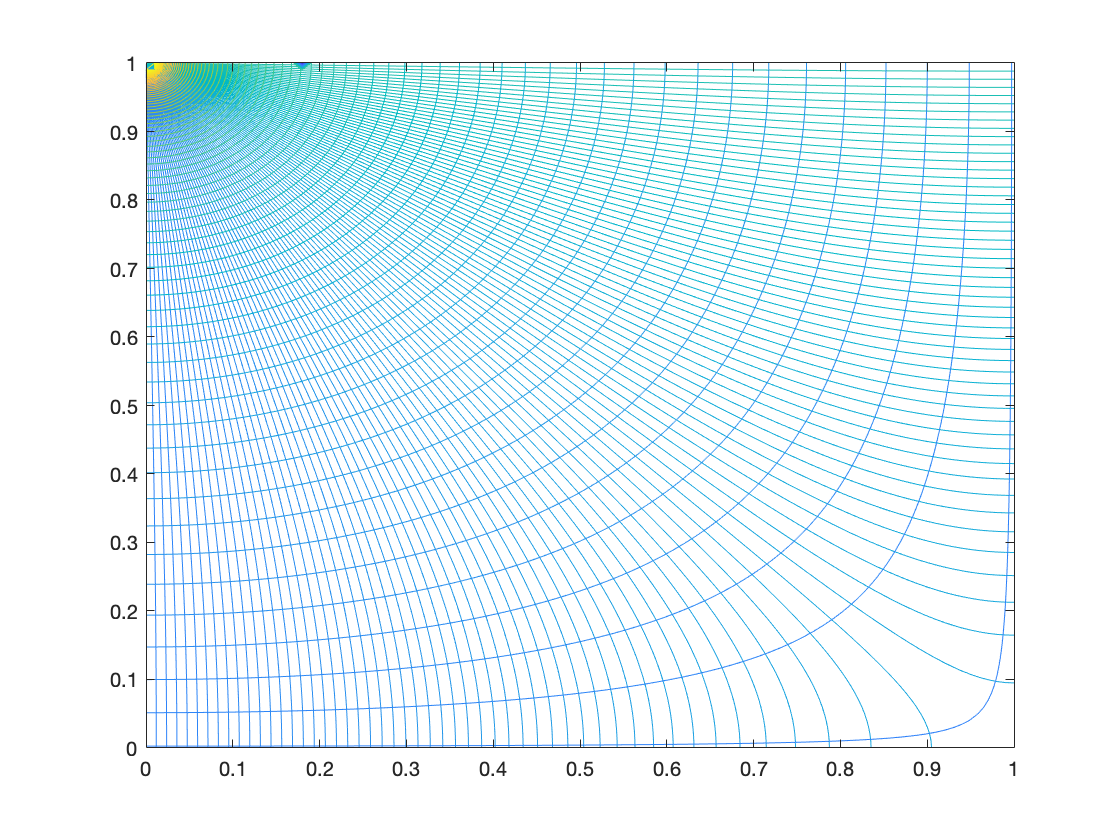

%plots
contour(X,Y,V,100)
hold on
contour(X,Y,chi,100)
hold off

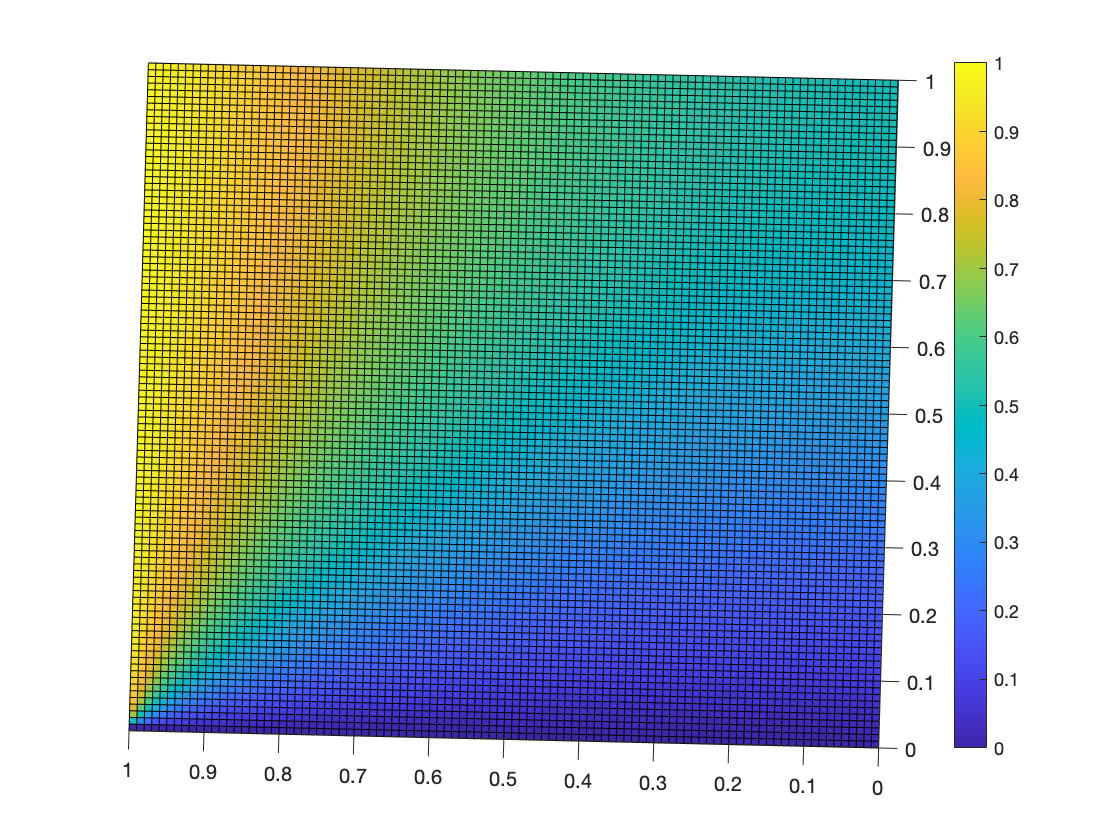


surf(X,Y,V)
colorbar

%below are various SC maps I was trying out, k is used above

function w = m(z)
w = i-(1/pi)*((z-1).^(1/2).*(z+1).^(1/2) + log(z + (z-1).^(1/2).*(z+1).^(1/2)))
end
function w = g(Z)
w = (1/pi)*(i.*(Z+1).^(1/2).*(Z-1).^(1/2)-i.*log(i*Z+(1-Z).^(1/2).*(1+Z).^(1/2))) + 1/2
end
function w = k(z)
w= (1/pi)*asin(z)+1/2
end
function w = l(z)
w = i*(1/2 - (1/pi)*((z-1).^(1/2).*(z+1).^(1/2) + asin(z)))
end